%объявление переменных
%syms x xp yp y m f a b l p xs ys xf yf ;

% задание начальных значений
xp = -2;
yp = -2;
a = 2;
b = 1;
c = sqrt(a^2-b^2);
xS = -c;
xF = c;

plot(xS, 0, 'or');
hold on
plot(xF, 0, 'or');
hold on
fi = 0:0.1:2*pi;
XE = a*cos(fi);
YE = b*sin(fi);
plot(XE, YE, '-k');
hold on
plot(xp, yp, 'xr');

% поиск лямбы в уравнении Лагранжа
p = [(1) (0) (-(c^4/2+xp^2*a^2+yp^2*b^2)) (c^2*(xp^2*a^2-yp^2*b^2)) (c^4*(c^4/16-xp^2*a^2/4-yp^2*b^2/4))];
f = roots(p);
disp(f);

  -5.6655 + 0.0000i
   4.2735 + 0.0000i
   0.6960 + 1.0794i
   0.6960 - 1.0794i




X = [];
Y = [];


% отбор подходящей лямбды - вещественной, большей нуля
for c = 1:4 % поскольку уравнение 4й степени, всегда будет не более 4х лямбд
    
    if (abs(imag(f(c))) < 10^(-6)) %проверка на отсутствие мнимой части и положительность
        m = f(c);
        disp(f(c));
        l= m - ((a^2+b^2)/2)
        x = a^2*xp/(a*a+l);
        y = b^2*yp/(b*b+l);
        X = [X x];
        Y = [Y y];
     
    end
end

   -5.6655



l = -8.1655

    4.2735



l = 1.7735


X

X =     1.9205   -1.3856


Y

Y =     0.2791   -0.7211


plot(X, Y, 'sb');
for j = 1:size(X, 2)
    D(j) = (X(j) - xp)^2 + (Y(j) - yp)^2;
end

D

D =    20.5648    2.0130



[Dmax Jmax] = max(D)

Dmax = 20.5648

Jmax = 1

x = X(Jmax)

x = 1.9205

y = Y(Jmax)

y = 0.2791

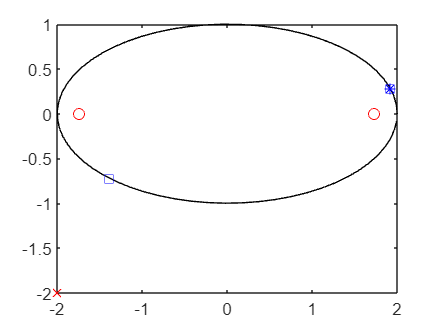

plot (x, y, '*b');

return;
%находим координаты нашей точки (х;y)
%x = a^2*xp/(a*a+l);
%y = b^2*yp/(b*b+l);
%disp(x);
%disp(y);

%построение траектории 

line([xS 0] , [x y],'Color','green','LineStyle','--')
hold on
line([x y] , [xF 0],'Color','red','LineStyle','--')

%fplot(f, [-10,10])

 